% betrachte den Winkel zwischen EIngangsgrößen als Ähnlichkeitsmaß
close all
clear
clc

load trainingsdaten.mat

 time = (0 : 0.1: length(x)/10).';
    
    % Testdaten
    xS = x(15 : 20:end,:);
    yS = y(15 : 20:end,1);
    uS = u(15 : 20:end,1);
    dxS = dx(15 : 20:end,1);
    uxS = [uS, xS];
    tS = time(15 : 20:end,:);
    nS = length(xS);
    
    %Trainingsdaten
    x = x(10 : 10:end,:);
    y = y(10 : 10:end,1);
    u = u(10 : 10:end,1);
    dx = dx(10 : 10:end,1);
    ux = [u,x];
    t = time(10 : 10:end,:);
    n = length(x);
    
    % Hyperparameter
    sigmaN = 0.35;
    sigmaF=100;
    l = 10;


axis = (1:1:nS).';

kS = zeros(n,1);


K = zeros(n);
xNorm = zeros(n,3);

for i = 1 : n
    xNorm(i,:) = x(i,:) / norm(x(i,:));
end


for i = 1 : n
    for j = 1 : n
        alpha= xNorm(i,:) * xNorm(j,:).';
        K(i,j) = exp(alpha^4-1);
        %K(i,j)= x(i,:)*x(j)
        %K(i,j)= dot(xNorm(i,:),xNorm(i,:));
    end
end

K_y = (K+sigmaN*eye(n))^-1;

mu_dx = zeros(size(uS));
s2 = zeros(size(mu_dx));


for i = 1:nS
    for j = 1 : n
         alpha = xNorm(j,:) * xS(i,:).' / norm(xS(i,:));
         kS(j)=exp(alpha^4-1);
    end
    mu_dx(i) = (kS.' * K_y * dx);
    s2(i) = 1 - (kS.'* K_y * kS);
     
end
mu = mu_dx+ xS(:,1); % Erwartungswert ist dx, daher Addition mit dem vorheringen Wert

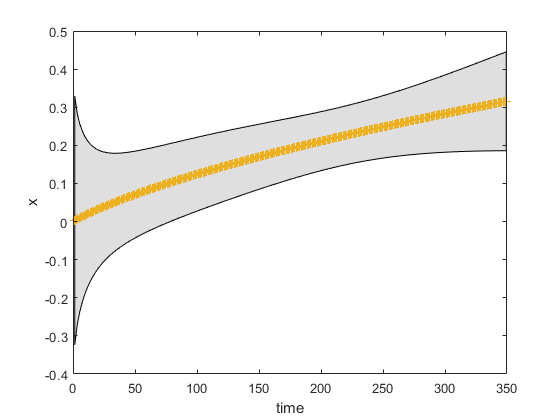

f = [mu+2*sqrt(s2); flipdim(mu-2*sqrt(s2),1)];
  
  %figure(1)
  fill([tS;flipdim(tS,1)], f, [7 7 7]/8)
  hold on; 
  plot(tS,mu); 
  plot(t,dx+x(:,1), '+')
  xlabel('time')
  ylabel('x')